%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% LOAD CORRESPONDING_POINTS, FRAME_INDEX_PAIRS, DIM_AND_CROP, VIDEOS %%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

inputs_path = '/Users/sidoodler/projects/asl/datasets/video_asl/inputs';
results_path = '/Users/sidoodler/projects/asl/datasets/video_asl/results';

%% FRAMES_SYNC_DIFF = FOR CAROLINE_SESSION_1: -3, FOR CAROLINE_SESSION_2: -3, FOR CAROLINE_SESSION_3: 0, FOR CAROLINE_SESSION_4: 0
%% FOR CAROLINE_SESSION_5: -1, FOR CAROLINE_SESSION_6: -1, FOR HANNA_SESSION_1: -1, FOR HANNA_SESSION_2: 1
%% FOR HANNA_SESSION_3: 0, FOR HANNA_SESSION_4: 2, FOR HANNA_SESSION_7: 2
%% FOR THE PUBLIC DATASET: 0

%%%%%%%%%%%%%%%%%%%%%% EDIT JUST THIS FOR EACH RUN %%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
session = 'video_Cory_sc108';
frames_sync_diff = 0;

video1 = 'left_edited';
video2 = 'right_edited';

v1 = VideoReader(strcat(inputs_path, '/asl_public/', session, '/', video1, '.mp4'));
v2 = VideoReader(strcat(inputs_path, '/asl_public/', session, '/', video2, '.mp4'));

f = 5376;  % ARRAY INITIALISATION
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

filename = strcat(results_path, '/', session, '/corresponding_points.txt');
[A, ~]=importdata(filename);
corresponding_coordinates = reshape(A, [168,size(A,2)/168])';  % ARRAY INITIALISATION

filename2 = strcat(results_path, '/', session, '/frame_index_pairs.txt');
[B, ~]=importdata(filename2);
keypoint_index_pairs = reshape(B, [2,size(B,2)/2])';  % ARRAY INITIALISATION

filename3 = strcat(results_path, '/', session, '/', video1, '/dim_and_crop.txt');
[C, ~]=importdata(filename3);  % ARRAY INITIALISATION

filename4 = strcat(results_path, '/', session, '/', video2, '/dim_and_crop.txt');
[D, ~]=importdata(filename4);  % ARRAY INITIALISATION

num_of_frames = size(keypoint_index_pairs, 1);  % ARRAY INITIALISATION
num_of_frames_for_fmatrix = 600;  % ARRAY INITIALISATION
fMatrix = zeros([3,3]);  % ARRAY INITIALISATION
F_list = zeros([3,3,num_of_frames_for_fmatrix]);  % ARRAY INITIALISATION
num_of_useful_f = 0;  % ARRAY INITIALISATION
inliersincorrect = 0;  % ARRAY INITIALISATION
inliers_list = zeros([num_of_frames_for_fmatrix,2]);  % ARRAY INITIALISATION

IntrinsicMatrix = [f 0 0; 0 f 0; C(2)/2 C(1)/2 1];  % ARRAY INITIALISATION

radialDistortion = [0 0];  % ARRAY INITIALISATION
camera_params = cameraParameters('IntrinsicMatrix',IntrinsicMatrix,'RadialDistortion',radialDistortion);  % NOT AN ARRAY

path = strcat(results_path, '/', session, '/all_good_fmatrices');

flag = 0;

if isfolder(path) == 0

    flag = 1;
    [status, msg, msgID] = mkdir(path);

end

if flag == 1

    parfor i = 1:num_of_frames_for_fmatrix
        
        if frames_sync_diff >= 0
            I1 = read(v1, keypoint_index_pairs(i, 2) + frames_sync_diff);  % ARRAY INITIALISATION
            I2 = read(v2, keypoint_index_pairs(i, 2));  % ARRAY INITIALISATION
        else
            I1 = read(v1, keypoint_index_pairs(i,2));  % ARRAY INITIALISATION
            I2 = read(v2, keypoint_index_pairs(i,2) - frames_sync_diff);  % ARRAY INITIALISATION
        end
        
        imagePoints1 = detectMinEigenFeatures(im2gray(I1), 'MinQuality', 0.01);  % NOT AN ARRAY
        tracker = vision.PointTracker('MaxBidirectionalError', 1, 'NumPyramidLevels', 5, 'MaxIterations', 300);  % NOT AN ARRAY
        
        imagePoints1 = imagePoints1.Location;  % ARRAY INITIALISATION
        initialize(tracker, imagePoints1, I1);
        
        [imagePoints2, validIdx] = step(tracker, I2);  % BOTH OUTPUTS ARE ARRAYS
        matchedPoints1 = imagePoints1(validIdx, :);  % ARRAY INITIALISATION
        matchedPoints2 = imagePoints2(validIdx, :);  % ARRAY INITIALISATION
        
        selection = matchedPoints1(:,1) >= C(2)-C(6) & matchedPoints1(:,1) <= C(2)-C(5) & matchedPoints1(:,2) >= C(3) & matchedPoints1(:,2) <= C(4)...
            & matchedPoints2(:,1) >= D(2)-D(6) & matchedPoints2(:,1) <= D(2)-D(5) & matchedPoints2(:,2) >= D(3) & matchedPoints2(:,2) <= D(4);  % ARRAY INITIALISATION
        
    %     display(sum(selection));
        
        matchedPoints1 = matchedPoints1(selection, :);
        matchedPoints2 = matchedPoints2(selection, :);
        
        matchedPoints1_all = zeros([42 + size(matchedPoints1, 1),2]);  % ARRAY INITIALISATION
        matchedPoints2_all = zeros([42 + size(matchedPoints2, 1),2]);  % ARRAY INITIALISATION
        
        for j = 1:size(corresponding_coordinates, 2)
            
            if mod(j, 4) == 1
                matchedPoints1_all(idivide(j,int32([4]),'ceil'), 1) = corresponding_coordinates(i,j);
                
            elseif mod(j, 4) == 2
                matchedPoints1_all(idivide(j,int32([4]),'ceil'), 2) = corresponding_coordinates(i,j);
            
            elseif mod(j, 4) == 3
                matchedPoints2_all(idivide(j,int32([4]),'ceil'), 1) = corresponding_coordinates(i,j);
                
            else
                matchedPoints2_all(idivide(j,int32([4]),'ceil'), 2) = corresponding_coordinates(i,j);
                
            end
            
        end
        
        matchedPoints1_all(43:end,:) = matchedPoints1;
        matchedPoints2_all(43:end,:) = matchedPoints2;
    
        % most time consuming function. Reduce NumTrials to get faster, less
        % accurate results
        
        [fMatrix, epipolarInliers] = estimateFundamentalMatrix(...
          matchedPoints1_all, matchedPoints2_all, 'Method', 'MSAC', 'NumTrials', 1000000);  % BOTH OUTPUTS ARE ARRAYS
    
    %     display(sum(epipolarInliers));
    
        inlierPoints1 = matchedPoints1_all(epipolarInliers, :);  % ARRAY INITIALISATION
        inlierPoints2 = matchedPoints2_all(epipolarInliers, :);  % ARRAY INITIALISATION
        
        [~, ~, num] = relativeCameraPose(fMatrix, camera_params, inlierPoints1, inlierPoints2);  % NUM IS AN ARRAY
        
        if num == 1
    
            F_list(:,:,i) = fMatrix;
            num_of_useful_f = num_of_useful_f + 1;
    
            file = strcat(path, '/', string(i), 'th_fmatrix', '.txt');
            fileID = fopen(file,'w');
            fprintf(fileID,'%6.12f %6.12f %6.12f\n',(fMatrix)');
            fclose(fileID);
    
        end
        
        display(i);
    
    end

else

    for i=1:num_of_frames_for_fmatrix
        
        filename = strcat(path, '/', string(i), 'th_fmatrix', '.txt');
    
        if isfile(filename) ~= 0
            
            [fMatrix, ~] = importdata(filename);
            F_list(:,:,i) = fMatrix;
    
        end
    
    end

end

    10

> In coder.internal.warning (line 8)
In vision.internal.ransac.msac (line 118)
In estimateFundamentalMatrix>msac (line 520)
In estimateFundamentalMatrix>estimateFundamentalMatrixAlg (line 451)
In estimateFundamentalMatrix (line 212)
In parallel_function>make_general_channel/channel_general (line 830)
In remoteParallelFunction (line 67)
> In coder.internal.warning (line 8)
In vision.internal.ransac.msac (line 118)
In estimateFundamentalMatrix>msac (line 520)
In estimateFundamentalMatrix>estimateFundamentalMatrixAlg (line 451)
In estimateFundamentalMatrix (line 212)
In parallel_function>make_general_channel/channel_general (line 830)
In remoteParallelFunction (line 67)


parfor i=1:3
    
    for j=1:3
        
        F_ij = F_list(i,j,:);  % ARRAY INITIALISATION
        F_ij = F_ij(1,1,F_ij ~= 0);
        F_ij = sort(F_ij);
        outliers_on_both_sides = cast(size(F_ij,3)/5, 'int32');  % ARRAY INITIALISATION
        
        if i==3 && j==3
            F_ij = F_ij(1,1,outliers_on_both_sides+1:end);
            
        else
            F_ij = F_ij(1,1,outliers_on_both_sides+1:size(F_ij,3)-outliers_on_both_sides);
            
        end
        
        fMatrix(i,j) = mean(F_ij, 3);
        
    end
    
end

display(num_of_useful_f);

num_of_useful_f = 498

display(fMatrix);

fMatrix =    -0.0000   -0.0000    0.0005
    0.0000   -0.0000    0.0349
   -0.0013   -0.0360    0.9981


ans = 122

    26



ans = 74

    22



ans = 71

    22



ans = 105

    31



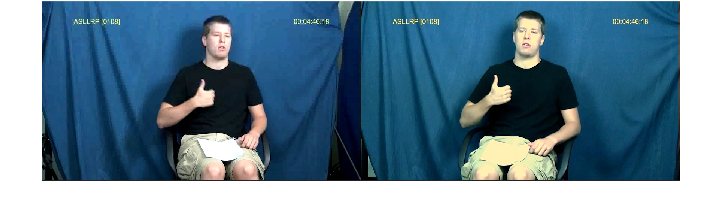

ans = 95

    24




path = strcat(results_path, '/', session, '/fundamental');

if isfolder(path) == 0
    [status, msg, msgID] = mkdir(path)
end

file = strcat(path, '/f', string(f), '_', string(num_of_useful_f), '_of_', string(num_of_frames_for_fmatrix), '.txt');
fileID = fopen(file,'w');
fprintf(fileID,'%6.12f %6.12f %6.12f\n',(fMatrix)');
fclose(fileID);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% ESTIMATE RELATIVE CAMERA POSE, GENERATE 3D POSE, ESTIMATE BONE 10-11 LENGTH %%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

filename = strcat(results_path, '/', session, '/fundamental', '/f', string(f), '_', string(num_of_useful_f), '_of_', string(num_of_frames_for_fmatrix), '.txt');
[fMatrix, ~] = importdata(filename);

R_list = zeros(3,3,5);  % ARRAY INITIALISATION
R_counts = zeros(1,1,5);  % ARRAY INITIALISATION
R_distinct = 0;  % ARRAY INITIALISATION
R_list_full = zeros(3,3,5);  % ARRAY INITIALISATION

t_list = zeros(1,3,5);  % ARRAY INITIALISATION
t_counts = zeros(1,1,5);  % ARRAY INITIALISATION
t_distinct = 0;  % ARRAY INITIALISATION
t_list_full = zeros(1,3,5);  % ARRAY INITIALISATION

for i=1:5

    frame_idx = randi(num_of_frames, 1);  % ARRAY INITIALISATION
    
    if frames_sync_diff >= 0
        I1 = read(v1, keypoint_index_pairs(frame_idx, 2) + frames_sync_diff);
        I2 = read(v2, keypoint_index_pairs(frame_idx, 2));
    else
        I1 = read(v1, keypoint_index_pairs(frame_idx,2));
        I2 = read(v2, keypoint_index_pairs(frame_idx,2) - frames_sync_diff);
    end
    
    imshowpair(I1, I2, 'montage'); 
    imagePoints1 = detectMinEigenFeatures(im2gray(I1), 'MinQuality', 0.01);
    tracker = vision.PointTracker('MaxBidirectionalError', 1, 'NumPyramidLevels', 5, 'MaxIterations', 300);
    
    imagePoints1 = imagePoints1.Location;
    initialize(tracker, imagePoints1, I1);
    
    [imagePoints2, validIdx] = step(tracker, I2);
    matchedPoints1 = imagePoints1(validIdx, :);
    matchedPoints2 = imagePoints2(validIdx, :);
    
    selection = matchedPoints1(:,1) >= C(2)-C(6) & matchedPoints1(:,1) <= C(2)-C(5) & matchedPoints1(:,2) >= C(3) & matchedPoints1(:,2) <= C(4)...
        & matchedPoints2(:,1) >= D(2)-D(6) & matchedPoints2(:,1) <= D(2)-D(5) & matchedPoints2(:,2) >= D(3) & matchedPoints2(:,2) <= D(4);
    
    sum(selection)
    
    matchedPoints1 = matchedPoints1(selection, :);
    matchedPoints2 = matchedPoints2(selection, :);
    
    matchedPoints1_all = zeros([42 + size(matchedPoints1, 1),2]);
    matchedPoints2_all = zeros([42 + size(matchedPoints2, 1),2]);
    
    for j = 1:size(corresponding_coordinates, 2)
        
        if mod(j, 4) == 1
            matchedPoints1_all(idivide(j,int32([4]),'ceil'), 1) = corresponding_coordinates(frame_idx,j);
            
        elseif mod(j, 4) == 2
            matchedPoints1_all(idivide(j,int32([4]),'ceil'), 2) = corresponding_coordinates(frame_idx,j);
        
        elseif mod(j, 4) == 3
            matchedPoints2_all(idivide(j,int32([4]),'ceil'), 1) = corresponding_coordinates(frame_idx,j);
            
        else
            matchedPoints2_all(idivide(j,int32([4]),'ceil'), 2) = corresponding_coordinates(frame_idx,j);
            
        end
        
    end
    
    matchedPoints1_all(43:end,:) = matchedPoints1;
    matchedPoints2_all(43:end,:) = matchedPoints2;
    
    [~, epipolarInliers] = estimateFundamentalMatrix(...
      matchedPoints1_all, matchedPoints2_all, 'Method', 'MSAC', 'NumTrials', 1000000);
    
    display(sum(epipolarInliers));
    
    inlierPoints1 = matchedPoints1_all(epipolarInliers, :);
    inlierPoints2 = matchedPoints2_all(epipolarInliers, :);
    
    [R, t, num] = relativeCameraPose(fMatrix, camera_params, inlierPoints1, inlierPoints2);  % R AND T ARE ARRAYS AND INITIALISED HERE
    
    R_list_full(:,:,i) = R(:,:,1);  % ARRAY INITIALISATION
    t_list_full(:,:,i) = t(1,:);  % ARRAY INITIALISATION
    
    flag1 = 0;  % ARRAY INITIALISATION
    flag2 = 0;  % ARRAY INITIALISATION
    
    for j=1:R_distinct
        
        if R(:,:,1) == R_list(:,:,j)
            R_counts(1,1,j) = R_counts(1,1,j) + 1;
            flag1 = 1;
            break;
        end
        
    end
    
    if flag1 == 0
        R_distinct = R_distinct + 1;
        R_list(:,:,R_distinct) = R(:,:,1);
        R_counts(1,1,R_distinct) = 1;
    end
    
    for j=1:t_distinct
        
        if t(1,:) == t_list(:,:,j)
            t_counts(1,1,j) = t_counts(1,1,j) + 1;
            flag2 = 1;
            break;
        end
        
    end
    
    if flag2 == 0
        t_distinct = t_distinct + 1;
        t_list(:,:,t_distinct) = t(1,:);
        t_counts(1,1,t_distinct) = 1;
    end

end


[~, idx] = max(R_counts);
R = R_list(:,:,idx);

[~, idx] = max(t_counts);
t = t_list(:,:,idx);
    
X0_list = zeros([2,3,num_of_frames]);  % ARRAY INITIALISATION
bone_length = 0;  % ARRAY INITIALISATION
coords_all = zeros([42,3,num_of_frames]);  % ARRAY INITIALISATION

camMatrix1 = cameraMatrix(camera_params, eye(3), [0 0 0]);  % ARRAY INITIALISATION
camMatrix2 = cameraMatrix(camera_params, R', -t*R');  % ARRAY INITIALISATION

for i = 1:num_of_frames

    matchedPoints1 = zeros([42,2]);  % ARRAY INITIALISATION
    matchedPoints2 = zeros([42,2]);  % ARRAY INITIALISATION
    
    for j = 1:size(corresponding_coordinates, 2)
        
        if mod(j, 4) == 1
            
            matchedPoints1(idivide(j,int32([4]),'ceil'), 1) = corresponding_coordinates(i,j);
            
        elseif mod(j, 4) == 2
            
            matchedPoints1(idivide(j,int32([4]),'ceil'), 2) = corresponding_coordinates(i,j);
        
        elseif mod(j, 4) == 3
            
            matchedPoints2(idivide(j,int32([4]),'ceil'), 1) = corresponding_coordinates(i,j);
            
        else

            matchedPoints2(idivide(j,int32([4]),'ceil'), 2) = corresponding_coordinates(i,j);
            
        end
        
    end
    
    points3D = triangulate(matchedPoints1, matchedPoints2, camMatrix1, camMatrix2);  % ARRAY INITIALISATION

    coords_all(:,:,i) = points3D;
    
    X0_1 = coords_all(1,:,i);  % ARRAY INITIALISATION
    X0_2 = coords_all(22,:,i);  % ARRAY INITIALISATION
    X0_list(:,:,i) = [X0_1; X0_2];
    
    d1 = sqrt(sum((coords_all(10,:,i) - coords_all(11,:,i)) .^ 2));
    d2 = sqrt(sum((coords_all(31,:,i) - coords_all(32,:,i)) .^ 2));

%     d1 = sqrt(sum((coords_all(1,:,i) - coords_all(10,:,i)) .^ 2));  % ARRAY INITIALISATION
%     d2 = sqrt(sum((coords_all(22,:,i) - coords_all(31,:,i)) .^ 2));  % ARRAY INITIALISATION
    
    bone_length = bone_length + d1 + d2;
    
end

bone_length = bone_length/(2*num_of_frames)

bone_length = 100.1130


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% SAVE 3D KEYPOINTS WITH OPTION TO SCALE OR NOT SCALE %%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% mode = 'no scaling' means raw 3d results will be saved.
% mode = 'scaling' means raw 3d results will first be scale normalised with
% the bone connecting joints 10 and 11, and then saved.

mode = 'no scaling'

mode = 'no scaling'

% mode = 'scaling'

% FOR MODE2, WE NEED TO VISUALLY CHECK WHICH ONE PRODUCES BETTER 3D POSE
% mode2 = 'average' 
mode2 = 'per frame'

mode2 = 'per frame'


for i = 1:num_of_frames
    
    if strcmp(mode, 'no scaling') == true
        
        path = strcat(results_path, '/', session, '/3d_keypoints_', string(f));
        if isfolder(path) == 0
            [status, msg, msgID] = mkdir(path)
        end
        path = strcat(path, '/', string(i), '.txt');
        fileID = fopen(path,'w');
        fprintf(fileID,'%6.4f %6.4f %6.4f\n',(coords_all(:,:,i))');
        fclose(fileID);
        
    elseif strcmp(mode, 'scaling') == true
        
        coords_all(1:21,:,i) = coords_all(1:21,:,i) - coords_all(1,:,i);
        coords_all(22:end,:,i) = coords_all(22:end,:,i) - coords_all(22,:,i);
        
        d1 = sqrt(sum((coords_all(10,:,i) - coords_all(11,:,i)) .^ 2));
        d2 = sqrt(sum((coords_all(31,:,i) - coords_all(32,:,i)) .^ 2));

%         d1 = sqrt(sum((coords_all(1,:,i) - coords_all(10,:,i)) .^ 2));
%         d2 = sqrt(sum((coords_all(22,:,i) - coords_all(31,:,i)) .^ 2));
        
        coords_all(1:21,:,i) = coords_all(1:21,:,i)/d1 ;
        coords_all(22:end,:,i) = coords_all(22:end,:,i)/d2 ;
        
        roots_mid_point = ( X0_list(1,:,i) + X0_list(2,:,i) )/2;  % ARRAY INITIALISATION
        
        roots_distance = sqrt(sum((X0_list(1,:,i) - X0_list(2,:,i)) .^ 2));  % ARRAY INITIALISATION
        
        if strcmp(mode2, 'per frame') == true
            
           bone_length = (d1 + d2)/2;
           
        end
        
        p1 = roots_mid_point + ( X0_list(1,:,i) - X0_list(2,:,i) ) / (bone_length*2);  % ARRAY INITIALISATION
        p2 = roots_mid_point + ( X0_list(2,:,i) - X0_list(1,:,i) ) / (bone_length*2);  % ARRAY INITIALISATION
        
        coords_all(1:21,:,i) = coords_all(1:21,:,i) + p1;
        coords_all(22:end,:,i) = coords_all(22:end,:,i) + p2;
        
        path = strcat(results_path, '/', session, '/3d_keypoints_scaled_', string(f));
        if isfolder(path) == 0
            [status, msg, msgID] = mkdir(path)
        end
        path = strcat(path, '/', string(i), '.txt');
        fileID = fopen(path,'w');
        fprintf(fileID,'%6.4f %6.4f %6.4f\n',(coords_all(:,:,i))');
        fclose(fileID);
        
    end
    
end

status = logical
   1



msg =

  0×0 empty char array


msgID =

  0×0 empty char array




R_counts

R_counts = R_counts(:,:,1) =

     5


R_counts(:,:,2) =

     0


R_counts(:,:,3) =

     0


R_counts(:,:,4) =

     0


R_counts(:,:,5) =

     0


t_counts

t_counts = t_counts(:,:,1) =

     5


t_counts(:,:,2) =

     0


t_counts(:,:,3) =

     0


t_counts(:,:,4) =

     0


t_counts(:,:,5) =

     0


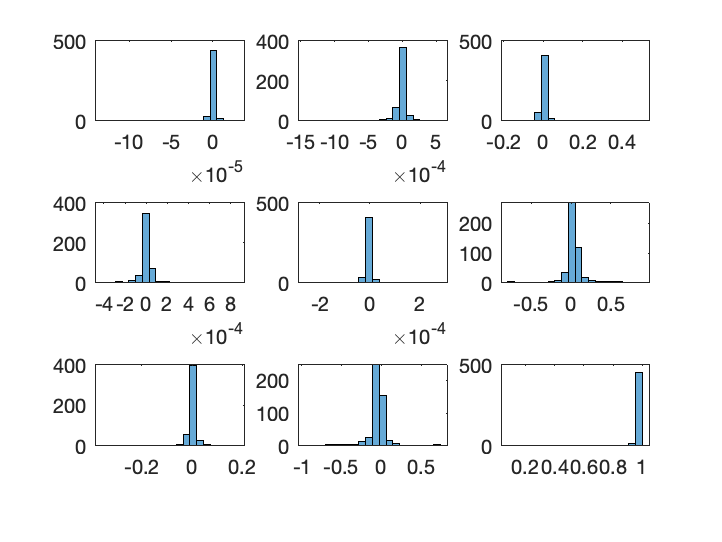

figure;

for i=1:3
    
    for j=1:3
        
        F_ij = F_list(i,j,:);
        F_ij = F_ij(1,1,F_ij ~= 0);
        subplot(3, 3, 3*(i-1)+j);
        histogram(F_ij, 20);
        
    end
    
end

> In coder.internal.warning (line 8)
In vision.internal.ransac.msac (line 118)
In estimateFundamentalMatrix>msac (line 520)
In estimateFundamentalMatrix>estimateFundamentalMatrixAlg (line 451)
In estimateFundamentalMatrix (line 212)
In parallel_function>make_general_channel/channel_general (line 830)
In remoteParallelFunction (line 67)
> In coder.internal.warning (line 8)
In vision.internal.ransac.msac (line 118)
In estimateFundamentalMatrix>msac (line 520)
In estimateFundamentalMatrix>estimateFundamentalMatrixAlg (line 451)
In estimateFundamentalMatrix (line 212)
In parallel_function>make_general_channel/channel_general (line 830)
In remoteParallelFunction (line 67)

num_of_useful_f = 452

fMatrix =    -0.0000   -0.0000    0.0028
    0.0000   -0.0000    0.0326
   -0.0032   -0.0334    0.9981


ans = 86

    31



ans = 122

    28



ans = 156

    29



ans = 121

    31



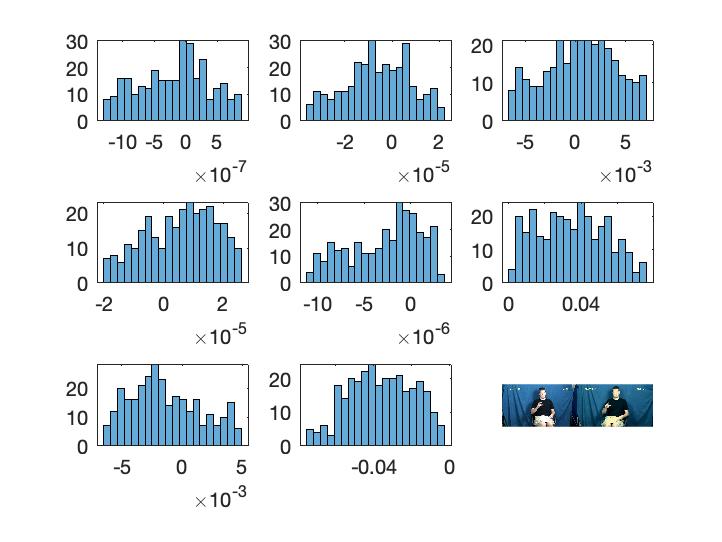

ans = 110

    23



bone_length = 0.1686

mode = 'no scaling'

mode2 = 'per frame'

R_counts = R_counts(:,:,1) =

     5


R_counts(:,:,2) =

     0


R_counts(:,:,3) =

     0


R_counts(:,:,4) =

     0


R_counts(:,:,5) =

     0


t_counts = t_counts(:,:,1) =

     5


t_counts(:,:,2) =

     0


t_counts(:,:,3) =

     0


t_counts(:,:,4) =

     0


t_counts(:,:,5) =

     0


> In coder.internal.warning (line 8)
In vision.internal.ransac.msac (line 118)
In estimateFundamentalMatrix>msac (line 520)
In estimateFundamentalMatrix>estimateFundamentalMatrixAlg (line 451)
In estimateFundamentalMatrix (line 212)
In parallel_function>make_general_channel/channel_general (line 830)
In remoteParallelFunction (line 67)
> In coder.internal.warning (line 8)
In vision.internal.ransac.msac (line 118)
In estimateFundamentalMatrix>msac (line 520)
In estimateFundamentalMatrix>estimateFundamentalMatrixAlg (line 451)
In estimateFundamentalMatrix (line 212)
In parallel_function>make_general_channel/channel_general (line 830)
In remoteParallelFunction (line 67)

num_of_useful_f = 519

fMatrix =    -0.0000   -0.0000   -0.0005
    0.0000   -0.0000    0.0313
   -0.0005   -0.0325    0.9962


ans = 83

    24



ans = 80

    22



ans = 96

    26



ans = 109

    28



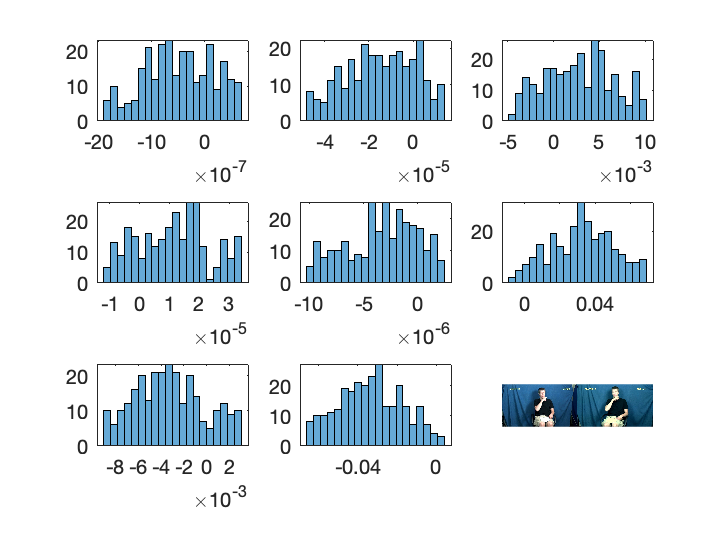

ans = 74

    23



bone_length = 0.0306

mode = 'no scaling'

mode2 = 'per frame'

R_counts = R_counts(:,:,1) =

     5


R_counts(:,:,2) =

     0


R_counts(:,:,3) =

     0


R_counts(:,:,4) =

     0


R_counts(:,:,5) =

     0


t_counts = t_counts(:,:,1) =

     5


t_counts(:,:,2) =

     0


t_counts(:,:,3) =

     0


t_counts(:,:,4) =

     0


t_counts(:,:,5) =

     0


> In coder.internal.warning (line 8)
In vision.internal.ransac.msac (line 118)
In estimateFundamentalMatrix>msac (line 520)
In estimateFundamentalMatrix>estimateFundamentalMatrixAlg (line 451)
In estimateFundamentalMatrix (line 212)
In parallel_function>make_general_channel/channel_general (line 830)
In remoteParallelFunction (line 67)
> In coder.internal.warning (line 8)
In vision.internal.ransac.msac (line 118)
In estimateFundamentalMatrix>msac (line 520)
In estimateFundamentalMatrix>estimateFundamentalMatrixAlg (line 451)
In estimateFundamentalMatrix (line 212)
In parallel_function>make_general_channel/channel_general (line 830)
In remoteParallelFunction (line 67)

num_of_useful_f = 487

fMatrix =    -0.0000   -0.0000    0.0013
    0.0000   -0.0000    0.0355
   -0.0022   -0.0365    0.9966


ans = 80

    22



ans = 75

    20



ans = 96

    22



ans = 79

    24



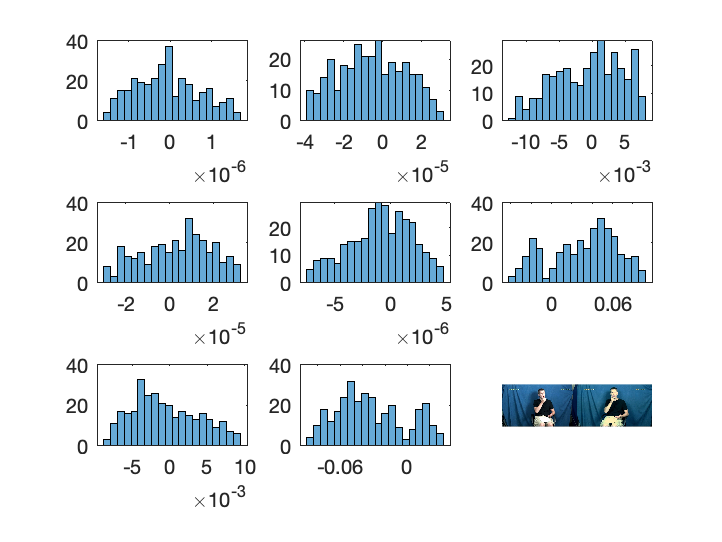

ans = 63

    22



bone_length = 343.2562

mode = 'no scaling'

mode2 = 'per frame'

status = logical
   1



msg =

  0×0 empty char array


msgID =

  0×0 empty char array



R_counts = R_counts(:,:,1) =

     5


R_counts(:,:,2) =

     0


R_counts(:,:,3) =

     0


R_counts(:,:,4) =

     0


R_counts(:,:,5) =

     0


t_counts = t_counts(:,:,1) =

     5


t_counts(:,:,2) =

     0


t_counts(:,:,3) =

     0


t_counts(:,:,4) =

     0


t_counts(:,:,5) =

     0


> In coder.internal.warning (line 8)
In vision.internal.ransac.msac (line 118)
In estimateFundamentalMatrix>msac (line 520)
In estimateFundamentalMatrix>estimateFundamentalMatrixAlg (line 451)
In estimateFundamentalMatrix (line 212)
In parallel_function>make_general_channel/channel_general (line 830)
In remoteParallelFunction (line 67)
> In coder.internal.warning (line 8)
In vision.internal.ransac.msac (line 118)
In estimateFundamentalMatrix>msac (line 520)
In estimateFundamentalMatrix>estimateFundamentalMatrixAlg (line 451)
In estimateFundamentalMatrix (line 212)
In parallel_function>make_general_channel/channel_general (line 830)
In remoteParallelFunction (line 67)

num_of_useful_f = 482

fMatrix =    -0.0000   -0.0000    0.0022
    0.0000   -0.0000    0.0104
   -0.0034   -0.0132    0.9963


ans = 104

    25



ans = 109

    19



ans = 92

    31



ans = 127

    34



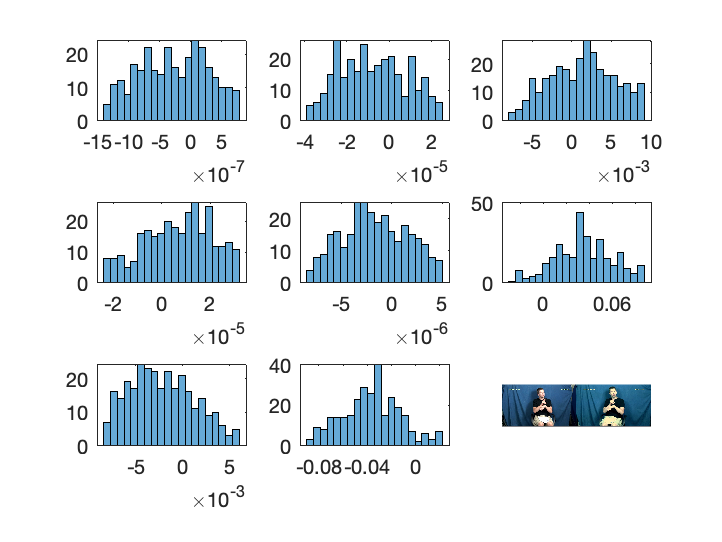

ans = 127

    30



bone_length = 0.0250

mode = 'no scaling'

mode2 = 'per frame'

status = logical
   1



msg =

  0×0 empty char array


msgID =

  0×0 empty char array



R_counts = R_counts(:,:,1) =

     5


R_counts(:,:,2) =

     0


R_counts(:,:,3) =

     0


R_counts(:,:,4) =

     0


R_counts(:,:,5) =

     0


t_counts = t_counts(:,:,1) =

     5


t_counts(:,:,2) =

     0


t_counts(:,:,3) =

     0


t_counts(:,:,4) =

     0


t_counts(:,:,5) =

     0


> In coder.internal.warning (line 8)
In vision.internal.ransac.msac (line 118)
In estimateFundamentalMatrix>msac (line 520)
In estimateFundamentalMatrix>estimateFundamentalMatrixAlg (line 451)
In estimateFundamentalMatrix (line 212)
In parallel_function>make_general_channel/channel_general (line 830)
In remoteParallelFunction (line 67)
> In coder.internal.warning (line 8)
In vision.internal.ransac.msac (line 118)
In estimateFundamentalMatrix>msac (line 520)
In estimateFundamentalMatrix>estimateFundamentalMatrixAlg (line 451)
In estimateFundamentalMatrix (line 212)
In parallel_function>make_general_channel/channel_general (line 830)
In remoteParallelFunction (line 67)

num_of_useful_f = 480

fMatrix =    -0.0000   -0.0000    0.0007
    0.0000   -0.0000    0.0391
   -0.0013   -0.0402    0.9958


ans = 111

    38



ans = 141

    34



ans = 110

    30



ans = 58

    21



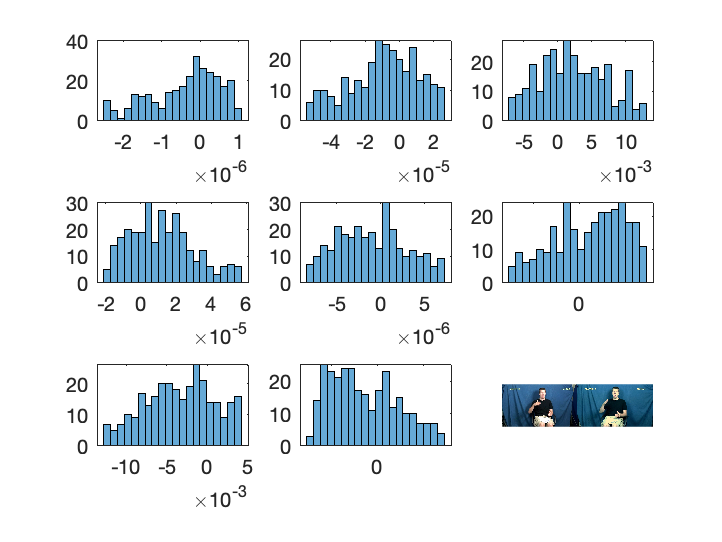

ans = 85

    23



bone_length = 0.0508

mode = 'no scaling'

mode2 = 'per frame'

status = logical
   1



msg =

  0×0 empty char array


msgID =

  0×0 empty char array



R_counts = R_counts(:,:,1) =

     5


R_counts(:,:,2) =

     0


R_counts(:,:,3) =

     0


R_counts(:,:,4) =

     0


R_counts(:,:,5) =

     0


t_counts = t_counts(:,:,1) =

     5


t_counts(:,:,2) =

     0


t_counts(:,:,3) =

     0


t_counts(:,:,4) =

     0


t_counts(:,:,5) =

     0


> In coder.internal.warning (line 8)
In vision.internal.ransac.msac (line 118)
In estimateFundamentalMatrix>msac (line 520)
In estimateFundamentalMatrix>estimateFundamentalMatrixAlg (line 451)
In estimateFundamentalMatrix (line 212)
In parallel_function>make_general_channel/channel_general (line 830)
In remoteParallelFunction (line 67)
> In coder.internal.warning (line 8)
In vision.internal.ransac.msac (line 118)
In estimateFundamentalMatrix>msac (line 520)
In estimateFundamentalMatrix>estimateFundamentalMatrixAlg (line 451)
In estimateFundamentalMatrix (line 212)
In parallel_function>make_general_channel/channel_general (line 830)
In remoteParallelFunction (line 67)

num_of_useful_f = 490

fMatrix =    -0.0000   -0.0000    0.0114
    0.0000   -0.0000   -0.0845
   -0.0127    0.0773    0.9781


ans = 168

    36



ans = 122

    30



ans = 103

    27



ans = 100

    27



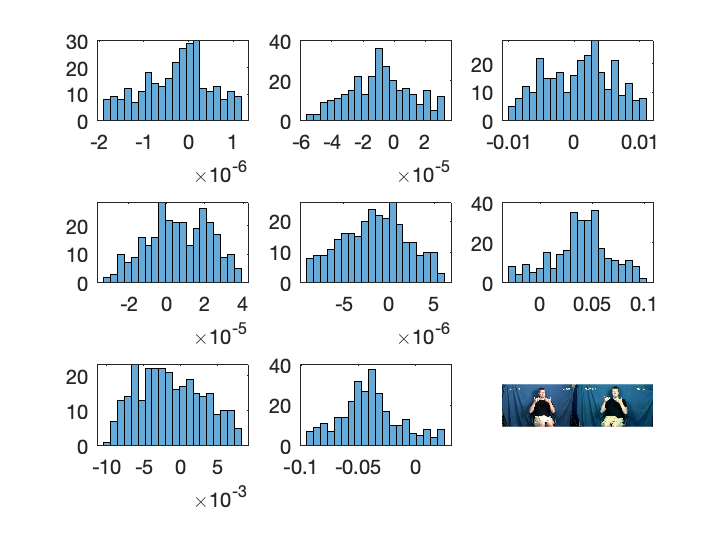

ans = 102

    24



bone_length = 0.0352

mode = 'no scaling'

mode2 = 'per frame'

status = logical
   1



msg =

  0×0 empty char array


msgID =

  0×0 empty char array



R_counts = R_counts(:,:,1) =

     5


R_counts(:,:,2) =

     0


R_counts(:,:,3) =

     0


R_counts(:,:,4) =

     0


R_counts(:,:,5) =

     0


t_counts = t_counts(:,:,1) =

     5


t_counts(:,:,2) =

     0


t_counts(:,:,3) =

     0


t_counts(:,:,4) =

     0


t_counts(:,:,5) =

     0


figure;

for i=1:3
    
    for j=1:3
        
        F_ij = F_list(i,j,:);
        F_ij = F_ij(1,1,F_ij ~= 0);
        F_ij = sort(F_ij);
        subplot(3, 3, 3*(i-1)+j);
        outliers_on_both_sides = cast(size(F_ij,3)/5, 'int32');
        
        if i==3 && j==3
            F_ij = F_ij(1,1,outliers_on_both_sides+1:end);
            
        else
            F_ij = F_ij(1,1,outliers_on_both_sides+1:size(F_ij,3)-outliers_on_both_sides);
            
        end
        
        histogram(F_ij, 20);
        
    end
    
end